# **Playing Table Tennis with Active Inference**

**Some of the language here is taken from the Duace paper & Karl's DEM_demo_MDP_DEM so it should be taken as an active notebook rather than a paper-ready document. **

*TODO:  x/y & pos/neg may be confused at times as matlab & roboschool have inverted coordinate systems. Everything works in the test scripts, this is a notebook.*

*TODO: MDP & Link factor for introceptive-propriocective model of game dynamics*

*TODO:  Decide whether or not to use linear indexing for acuity (see exteroceptive link factor). Using linear indicies requires 86k possible observations, each of which must be represented by a (256,126,5) matrix (1.3870e+10 elements!). Sparsifying this representation is problematic as ndsparse mats aren't supported in matlab and this will almost certainly break downstream spm routines.*

*MAYBE: Having a prior on fast responses at the exteroceptive level could have interestng effects on saccades - BMR of acuity -  learn lots or live with inefficiency?*

## MuJoCo 

[http://www.mujoco.org/book/computation.html](http://www.mujoco.org/book/computation.html)

MujoCo is a 3d physics engine that serves as a proxy for the real world. It simulates the dynamics and physical properties of objects in the game, namely the positions and velocities of the player paddle, opponent paddle and the ball. MuJoCo computes forward and inverse dynamics in continuous time and for this environment uses the semi-implicit Euler method for numerical integration. This results in smooth collisions and PID-esque actuators for the player paddles. *Maybe something about link between the extended kalman filter & PID controllers (observer/estimation vs feedback/control) - chapters 6 & 7 here *[*http://www.cds.caltech.edu/~murray/books/AM08/pdf/am08-complete_30Aug11.pdf*](http://www.cds.caltech.edu/~murray/books/AM08/pdf/am08-complete_30Aug11.pdf) 

## The Pong Environment

The Pong environment, originally developed with MujoCo,is provided by 'Roboschool', an open-source software for robot simulation, integrated with OpenAI Gym.

## Image Processing

The roboschool 'Pong' environment contains a camera with user definable properties. The location and rotation have been set such that the camera is above the playing field looking downward with the whole field in view at a resolution of 256x128 (width/height) pixels.

Nb. the resolution of the imagespresented here are 360x240 but this will be corrected later. 

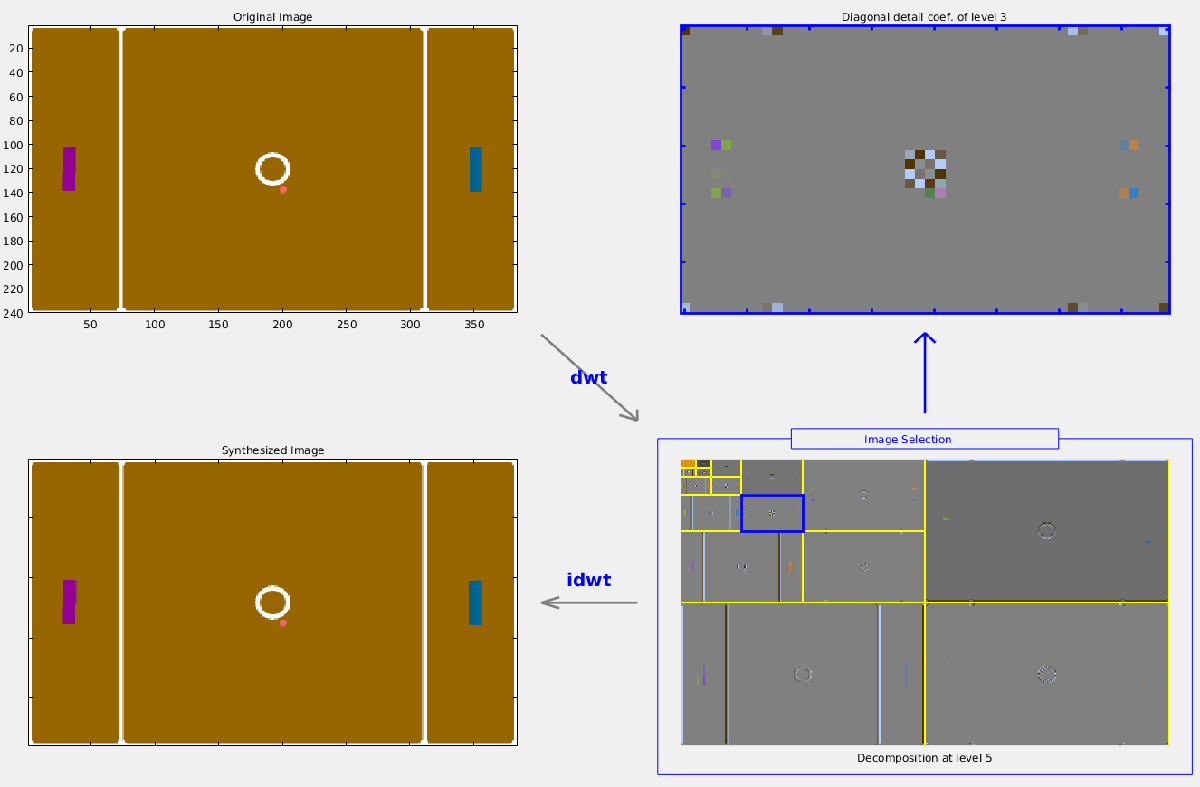

  Figure 1. Top left - Observation (pixels) returned from roboschool. Top right - Diagonial detail coefficients at level 3. Bottom left -     reconstruction of the original image produced via inverse wavelet transform. Bottom right - Decomposition of original image to 5 levels. 

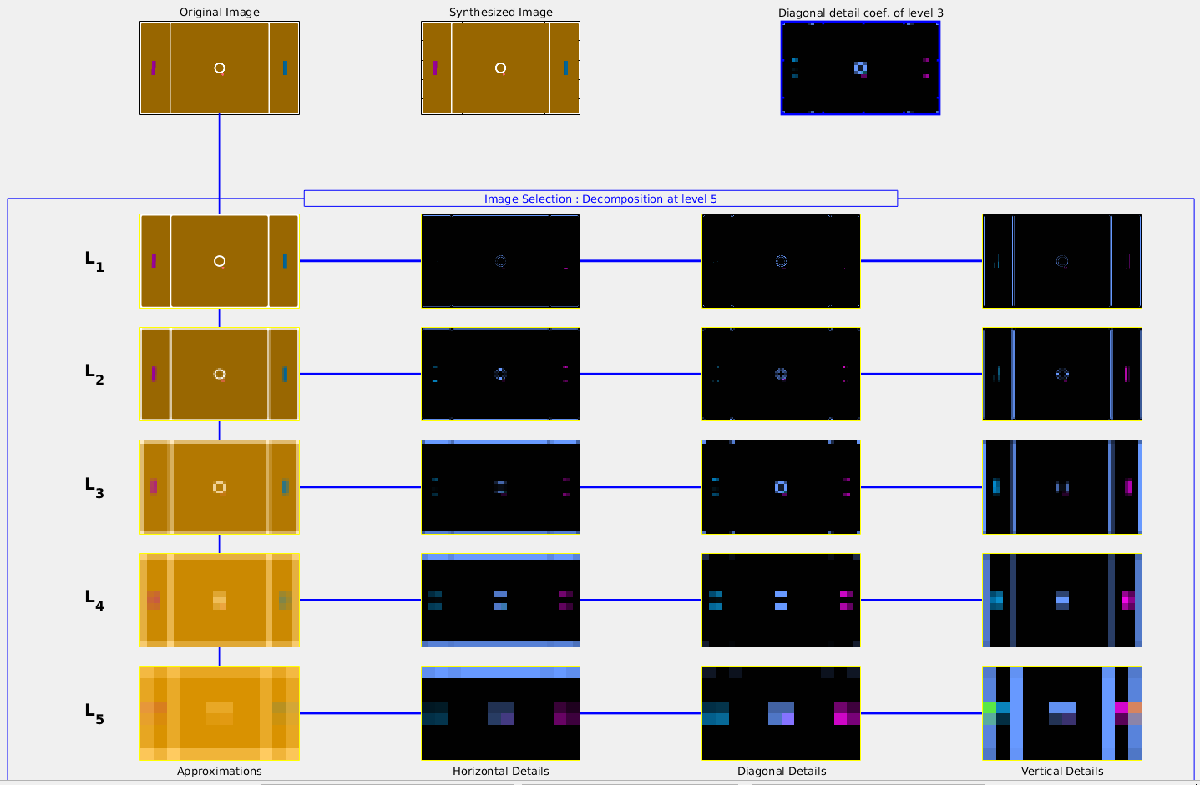

Figure 2. Detailed visualiation of coefficients at each level. 

x_pixels = 384; % should be 256
y_pixels = 240; % should be 128
nh = 5;         % levels of decomposition
nObjs = 3;

% image dimensions at each level of acuity held in (2,h) vector
xy = round([x_pixels * 1./2.^(1:nh); y_pixels * 1./2.^(1:nh)]);

## Fovea-Based Model

This model is based on Duace 2018 (unpublished).  Vision is reduced to a foveated transform of the image sampled from the game 'camera', effectively performing localized compression at a given level of acuity. This view provides high spatial frequencies (pixel density) at the center of foveation, with low spatial frequencies at the periperiphery.

Given a viewpoint (x,y,g), where **x** is the row index, **y** is the column index and **h** is the spatial scale, we can build a 2D Haar wavelet 'pyramid' corresponding to a visual field (observation). Each visual field is made of three wavelet coefficients $v_{xyh}  \in {R}^3$ obtained from a horizontal, a vertical and an oblique filter at location (x,y) and scale h. The multiscale visual information $v_{xy} \in R^{15}$  available at coordinates (x,y) corresponds to a set of 5 coefficient triplets, $v_{xy} = \{v_{x,y,5} ,
v_{[x/2], [y/2], 4},  
v_{[x/4], [y/4], 3}, 
v_{[x/8], [y/8], 2}, 
v_{[x/16], [y/16], 1}\}$ such that each multiscale visual field owns 15 coefficients (as opposed to the 32768 pixels in the original image). 

## **Learning**

A weak generative model is learned for each u = (x,y,h) making a total of 10912 (nModels) weak models. 

for i = 1:5
    [c, s] = wavedec2(rand(256, 128),i,'haar');
    n(i) = numel(appcoef2(c,s,'haar',i));
end
nModels = sum(n);

For each category O{1} and each gaze orientation u, a generative model is built over parameter set $\theta_{z,u} = (p_{z,u}, \mu_{z,u}, \sigma_{z,u})$ so that $\forall z,u,\tilde{x}_{z,u}  \ \tilde  \ \ B(p_{z,u} ) \times \mathcal{N}(\mu_{z,u}, \sigma_{z,u})$ with **B** a Bernouilli distribution and **N** a multivariate Gaussian. The Bernouilli reports the case where the coefficient triplet is null in the considered portion of the image, (this also provides the basis for explicit (pre-hoc BMR) priors  i.e player paddle cant go beyond a given horizontal threshold) which results in discarding the corresponding triplet from the Gaussian moments calculation. Each resulting weak generative model $p(X|z,u)$ is a mixture of Bernouilli-gated Gaussians over the 3 game pieces. For the recognition model, a posterior can here be calculated explicitly using Bayes rule, i.e $q(Z|x,u) = softmax \ lnp(x|Z,u)$.

% Run in this order to train & validate generative models
% It's feasible that we may be able to integrate this training procedure into 
% the simulations, but it will be tricky so we should do everything else first
train_models()
test_gaussians()
test_models()

Important conceptual change to experimental design - we have defined the visual space & introduced the concept of model space, both are 2d, discrete and intrinsically linked. Link factors determine where and when each can be used. **Continous** **game (prioprioceptive/roboschool/pong) space cannot be linked with foveal (continuous-exteroceptive) model space unless through the discrete exteroceptive/visual MDP model.  **

## Markovian model at the sensory level (MDP): Discrete States 

There are two outcome modalities (where, what), encoding one of 3 game objects and one of x*y*h possible locations (or 86676 linear indices!).  The hidden states have 3 factors; x-location (nx at maximum acuity), y-location (ny at maximum acuity) and acuity (nh). Prior preferences are driven by outcomes at the proprioceptive level (TODO).

% Discrete actions
U(1,:,1) = 1:xy(1,1); % max num x coords
U(1,:,2) = 1:xy(2,1); % max num y coords
U(1,:,3) = 1:nh;      % levels of acuity

% Observation Model - A{1} where
% having a unique location for every xyh requires >80GB A mat- should use h=2 for now
for f3 = 1:5
    for f1 = 1:xy(1,f3)
        for f2 = 1:xy(2,f3)
            % 1,1 & 2,1 are used instead of 1,f3 as in reality - each h has the same 
            % number of elements, but are zeroed out
            location = sub2ind([xy(1,1) xy(2,1) nh],ceil(f1/16), ceil(f2/16), f3); 
            A{1}(location, f1,f2,f3) = 1; % where
        end
    end
end

% Observation Model - A{2} what
for o = 1:nObjs
    for f3 = 1:5
        for f1 = 1:xy(1,f3)
            for f2 = 1:xy(2,f3)
                A{2}(o,f1,f2,f3) = 1; % what                
            end
        end
    end
end

% Veridical Observation and Transition Matrices 
for f3 = 1:nh
    for f1 = 1:xy(1,f3)
        for f2 = 1:xy(2,f3)
            B{2}(f2,:,f2) = 1; % new y under y
        end
        B{1}(f1,:,f1) = 1; % new x under x
    end
    B{3}(f3,:,f3) = 1; % new acuity under h
end

% Prior Utility - Follow the ball for nT
C{what} = repmat([0 0 1],nT)';
mid_at_h1 = sub2ind([sum(xy(1,1)) sum(xy(2,1)) nh],xy(1,1)/2, xy(2,1)/2, 1);

% 'Where' prior should be overwritten by top-down empirical priors mediated by the 
% continuous proprioceptive model - we can manualy do this in the game loop (for now)
C{where} = ones(1,nT) * mid_at_h1;

% Initial view point
D{F1} = round(xy(1,1)/2);   % centre x
D{F2} = round(xy(2,1)/2);   % centre y
D{F3} = 1;                  % highest acuity 

## Generative model at the sensory level (DEM): Continuous States 

This level of model specification concerns the sampling of continuous data; here, visual stimuli is encoded in a global structure (STIM). 

global STIM

% Possible Hypotheses (Objects)
STIM.H   = [1 2 3]; 

% Pretrained Generative Models
STIM.G = load('models.mat'); % generative models at each xyh

% Foveate - specify coordinates of Haar pyramid based on angle & focus
STIM.FOCUS  = @(x) round([x(1:2);x(1:2)/2;x(1:2)/4;x(1:2)/8;x(1:2)/16])';

% Sample - fill pyramid with coefficients
STIM.SAMPLE = @(v,x) [[v{1}{x(1)}],[v{2}{x(2)}],[v{3}{x(3)}],[v{4}{x(4)}],[v{5}{x(5)}]];

% Locations
for i  = 1:h
   % Roboschool - 'Locations Continuous'
   STIM.LC{i}{1} = linspace(-1,1,xy(1,i));    % x
   STIM.LC{i}{2} = linspace(-1,1,xy(2,i));    % y
   % Saccades   - 'Locations Discrete' - Coords of models
   STIM.LD{i}{1} = 1:xy(1,i);                 % x
   STIM.LD{i}{2} = 1:xy(2,i);                 % y
end

The hidden causes of this generative model correspond to one attracting location and the content or stimulus that will be sampled at that location. The dynamics or hidden states in this level of the model are simple: the attracting location simply attracts the point of foveal fixation.

% generative model
%==========================================================================
M(1).E.s = 1/2;                               % smoothness
M(1).E.n = 2;                                 % order of
M(1).E.d = 1;                                 % generalised motion

% hidden states
%--------------------------------------------------------------------------
[x(1), x(2), x(3)] = ind2sub([sum(xy(1,1)) sum(xy(2,1)) nh],mid_at_h1); % oculomotor angle - centre at h1
v.x                = [0;0];                                             % fixed (attracting) point - centre at h1
v.h                = sparse(3,1,1);                                     % hypothesis - ball
g                  = 'gx_sample_image';

% level 1: Displacement dynamics and mapping to sensory/proprioception
%--------------------------------------------------------------------------
M(1).f = @(x,v,P) (v.x - x);
M(1).g = @(x,v,P) spm_vec(x,g(x - v.x,v.h));
M(1).x = x;                                   % hidden states
M(1).V = 8;                                   % error precision (g)
M(1).W = 8;                                   % error precision (f)

% level 2:
%--------------------------------------------------------------------------
M(2).v = v;                                   % priors
M(2).V = [exp(8) exp(8) ones(1,nh)];

% generative process
%==========================================================================

% first level
%--------------------------------------------------------------------------
G(1).f = @(x,v,a,P) a; % g.f does m.f 
G(1).g = @(x,v,a,P) spm_vec(x,g(x - v.x,v.h));
G(1).x = x;                                  % hidden states
G(1).V = exp(8);                            % error precision
G(1).W = exp(8);                            % error precision

% G.U does what acuity/h should be doing in 'precision space' 
% i.e in a modulatory fashion rather than explicitly - see spm_adem for what more detail
% It was my original intention (this implementation) to hard-code an update for this factor B{3} at the 
% end of every expermental epoch based on learned/inferred precision. It may be silly to 
% involve acuity in the experimental design, but I have no idea how to re-factor the DEM code to 
% accomodate the learning of 'gain'.
% An interesting project might consider:
% https://www.sciencedirect.com/science/article/pii/S0377042707005080 
% 'Restriction operators for multigrid algorithms' or something like that
% G(1).U = [0 0 <interesting>];               % gain 

% second level
%--------------------------------------------------------------------------
G(2).v = v;                                  % visual field
G(2).a = [0;0;0];                            % action forces [x y acuity]
G(2).V = exp(16);

% generate and invert
%==========================================================================
DEM.G  = G;
DEM.M  = M;

% solve and save saccade
%--------------------------------------------------------------------------
DEM    = spm_MDP_DEM(DEM,demi,O,o); 

##  Continuous Exteroceptive to Discrete Proprioceptive Link Factor

 
 % evaluate true and priors over causes given discrete states
%--------------------------------------------------------------------------
o     = [mid_at_h1,3];

O{1}  = spm_softmax(sparse(sum(xy(1,:)) * sum(xy(2,:)), 1, mid_at_h1)); % start at centre (h=1)
O{2}  = spm_softmax(sparse(3,                           1, 3));         % start looking at ball

% links from states at the current level to outcomes at the next level
%--------------------------------------------------------------------------
N     = 80;              % length of data sequence
nHyp  = length(STIM.H);  % number of hypotheses
nl    = sum(xy(:));      % number of locations / models 

% get linear index of (x,y,h) at 
for object = 1:nHyp
    for f3 = 1:5        
        for f1 = 1:xy(1,h)
            for f2 = 1:xy(2,h)
                location = sub2ind([xy(1,1) xy(2,1) nh],f1, f2, f3);
                c = [STIM.LC{h}{1}(f1) ; STIM.LC{h}{2}(f2)]; % [x ; y]
                u = [STIM.LC{h}{1}(f1) ; STIM.LC{h}{2}(f2)];
                demi.U{location,object} = u * ones(1,N); % hidden causes
                demi.C{location,object} = c * ones(1,N); % true   causes
            end
        end
    end
 end
 

## Generative model at the Proprioceptive level (DEM): Continuous States 

Third level (Continuous: Proprioceptive )

The hidden states are comprised of the physical properties (position and velocity) of each game piece. 

Action influences the position of the players paddle in the y dimension. 

% 

% Generative Model 
% estimate location of object - make continuous saccade- sample with duace
% report the 'what' - 
pong_model_c.M(1).f = 'fx_pong.m';
pong_model_c.M(1).g = @(x,v,P) x;
% TODO this fails because of the img field (delete that and handle somewhere else)
pong_model_c.M(2).v = cell2mat(struct2cell(load('lvl2_test_data.mat')));

% Generative Process -
pong_model_c.G(1).f = @(x,v,a,P) a; % pass action to game
pong_model_c.G(1).g = @(x,v,a,P) x; % pass data from game
pong_model_c.G(2).v = cell2mat(struct2cell(load('lvl2_test_data.mat')));
pong_model_c.G(2).a  = 0;
 

** Continuous Proprioceptive to Discrete Proprioceptive Link Factor**

% links points on the continuous range [-1 1] to 
% discrete viewpoints(h,x,y) 
% n.b any given continuous point (x,y) must be represented a
% at every h --- 1 continuous (x,y) tuple = 5 discrete(x,y) tuples
pong_demi = roboschool_to_gridspace(x_pixels, y_pixels, N); 

Fourth level (Discrete: Introceptive/Proprioceptive)

There are three outcome modalities (what, where), encoding each of the three objects and their lcoations.  The hidden states have 2 factors; x-location (nx at maximum acuity) and y-location (ny at maximum acuity).